## Basic syntax of calling Python functions from MATLAB

All Python functions in MATLAB have the same basic syntax:

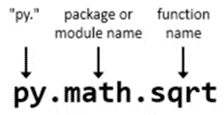

The basic example that I give to kick things off is usually calling the square root function from the [math module](https://docs.python.org/3/library/math.html), that is part of the Python standard library. It makes little sense to call mathematics functions in Python from MATLAB, but it is easy to compare the result with what you would expect directly from MATLAB:

In the MATLAB Command Window:

`>> py.math.sqrt(42)`

In a MATLAB Live Script:

py.math.sqrt(42)

ans = 6.4807

We can create Python data structures from within MATLAB:

py.list([1,2,3])

ans =   Python list with values:

    [1.0, 2.0, 3.0]

    Use string, double or cell function to convert to a MATLAB array.


py.list({1,2,'a','b'})

ans =   Python list with values:

    [1.0, 2.0, 'a', 'b']

    Use string, double or cell function to convert to a MATLAB array.


s = struct('a', 1, 'b', 2)

s = struct with fields:
    a: 1
    b: 2


d = py.dict(s)

d =   Python dict with no properties.

    {'a': 1.0, 'b': 2.0}


And we can run methods on those data structures from the MATLAB side:

methods(d)

Methods for class py.dict:

char        clear       copy        dict        eq          ge          get         gt          items       keyHash     keyMatch    keys        le          lt          ne          pop         popitem     setdefault  struct      update      values      

Static methods:

fromkeys    

Call "methods('handle')" for methods of py.dict inherited from handle.



d.get('a')

ans = 1